# Remove Noise By Adaptive Filtering 

This example shows how to use the wiener2 function to apply a Wiener filter (a type of linear filter) to an image adaptively. The Wiener filter tailors itself to the local image variance. Where the variance is large, wiener2 performs little smoothing. Where the variance is small, wiener2 performs more smoothing. This approach often produces better results than linear filtering. The adaptive filter is more selective than a comparable linear filter, preserving edges and other high-frequency parts of an image. In addition, there are no design tasks; the wiener2 function handles all preliminary computations and implements the filter for an input image. wiener2, however, does require more computation time than linear filtering. wiener2 works best when the noise is constant-power ("white") additive noise, such as Gaussian noise. The example below applies wiener2 to an image of Saturn with added Gaussian noise. Read the image into the workspace.

RGB = imread("Kaguya_Sama.png");

Convert the image from truecolor to grayscale.

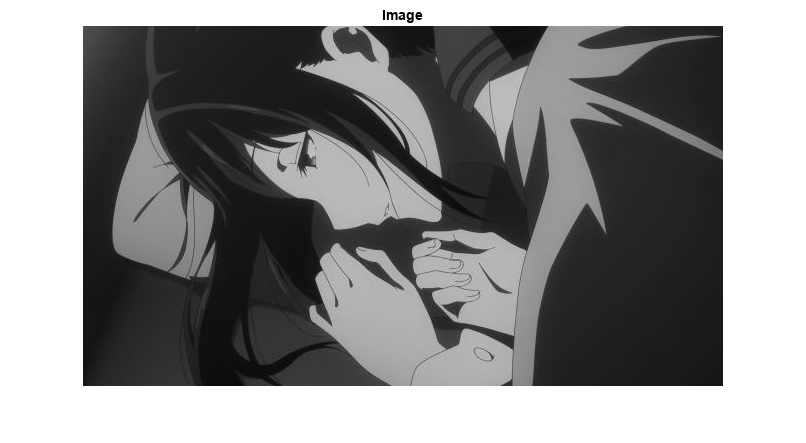

I = im2gray(RGB);
imshow(I);
title('Image');

Add Gaussian noise to the image.

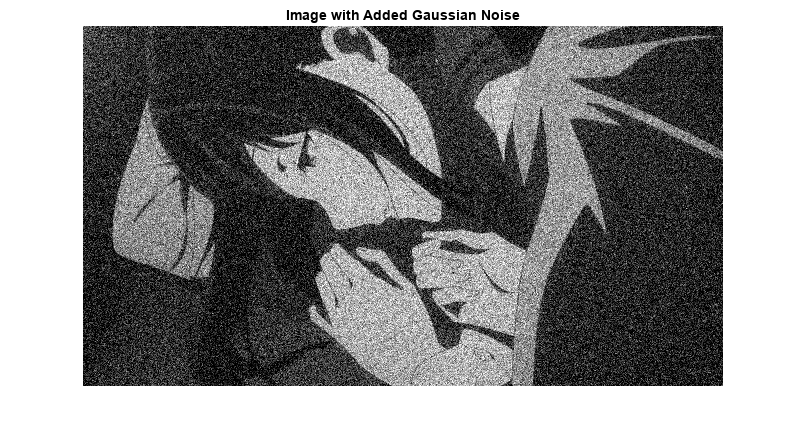

J = imnoise(I,'gaussian',0,0.025);
imshow(J);
title('Image with Added Gaussian Noise');

Remove the noise using the wiener2 function.

K = wiener(J,[5 5]);

Display the processed image. 

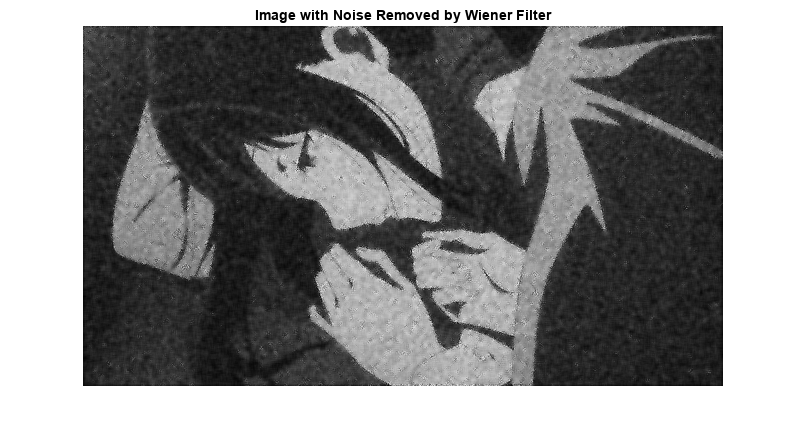

figure
imshow(K);
title('Image with Noise Removed by Wiener Filter');